# Laboratorio 5

## Punto 4: Métodos iterativos, condicionamiento y criterios de convergencia.

**4.1**

clear; clc; close all;

d = [2 0 2 3 2 2 1 1 5];

d7 = d(7);
d8 = d(8);
d9 = d(9);

p = 1 + 0.05*d7;
q = 1 + 0.05*d8;
s = 1 + 0.05*d9;

% Sistema base
A = [5+p, -1,   0,  1;
    -1,  5+q, -1,  0;
    0,  -1,  4+s, -1;
    1,   0,  -1,  5];

b = [6 + 0.1*d7;
    -8 - 0.1*d8;
    9 + 0.1*d9;
    1.5];

xref = A\b;

kappaA = cond(A);
rcondA = rcond(A);

fprintf('Cond(A)  = %.8e\n', kappaA);

Cond(A)  = 1.93383007e+00


fprintf('rcond(A) = %.8e\n\n', rcondA);

rcond(A) = 4.24104734e-01




%% Dominancia diagonal

diagA = abs(diag(A));
sumaFueraDiagonal = sum(abs(A),2) - diagA;

dominancia = diagA > sumaFueraDiagonal;

tablaDominancia = table((1:4)', diagA, sumaFueraDiagonal, dominancia, ...
    'VariableNames', {'Fila','Diagonal','Suma_No_Diagonal','Dominante'});

disp(tablaDominancia);

    Fila    Diagonal    Suma_No_Diagonal    Dominante
    ____    ________    ________________    _________

     1        6.05             2              true   
     2        6.05             2              true   
     3        5.25             2              true   
     4           5             2              true   




%% Matrices de iteración

D = diag(diag(A));
L = tril(A,-1);
U = triu(A,1);

BJ = -D\(L+U);
BGS = -(D+L)\U;

% Radios espectrales
rhoJ = max(abs(eig(BJ)));
rhoGS = max(abs(eig(BGS)));

fprintf('\nRadio espectral Jacobi       = %.8f\n', rhoJ);


Radio espectral Jacobi       = 0.26956627


fprintf('Radio espectral Gauss-Seidel = %.8f\n', rhoGS);

Radio espectral Gauss-Seidel = 0.12402523


%% Jacobi y Gauss-Seidel

x0 = zeros(4,1);
tol = 1e-8;
maxIter = 500;

% ---------------- JACOBI ----------------
xJ = x0;
resJ = zeros(maxIter,1);

for kJ = 1:maxIter

    xAnterior = xJ;

    xJ = D\(b - (L+U)*xAnterior);

    rJ = b - A*xJ;
    resJ(kJ) = norm(rJ,inf)/norm(b,inf);

    if resJ(kJ) < tol
        break;
    end
end

resJ = resJ(1:kJ);

errorJ = norm(xJ-xref,inf);


% ------------- GAUSS-SEIDEL -------------
xGS = x0;
resGS = zeros(maxIter,1);

for kGS = 1:maxIter

    xAnterior = xGS;

    xGS = (D+L)\(b-U*xAnterior);

    rGS = b-A*xGS;
    resGS(kGS) = norm(rGS,inf)/norm(b,inf);

    if resGS(kGS) < tol
        break;
    end
end

resGS = resGS(1:kGS);

errorGS = norm(xGS-xref,inf);


%% Resultados

fprintf('\n--- JACOBI ---\n');


--- JACOBI ---


fprintf('Iteraciones: %d\n',kJ);

Iteraciones: 14


fprintf('Residuo relativo: %.8e\n',resJ(end));

Residuo relativo: 6.87900731e-09


fprintf('Error respecto a xref: %.8e\n',errorJ);

Error respecto a xref: 1.25784485e-08



fprintf('\n--- GAUSS-SEIDEL ---\n');


--- GAUSS-SEIDEL ---


fprintf('Iteraciones: %d\n',kGS);

Iteraciones: 10


fprintf('Residuo relativo: %.8e\n',resGS(end));

Residuo relativo: 1.08559515e-09


fprintf('Error respecto a xref: %.8e\n',errorGS);

Error respecto a xref: 1.69900916e-09



disp('Solución de referencia:');

Solución de referencia:


disp(xref);

    0.7742
   -0.9255
    1.7267
    0.4905




disp('Solución Jacobi:');

Solución Jacobi:


disp(xJ);

    0.7742
   -0.9255
    1.7267
    0.4905




disp('Solución Gauss-Seidel:');

Solución Gauss-Seidel:


disp(xGS);

    0.7742
   -0.9255
    1.7267
    0.4905



Se espera que ambos métodos converjan hacia la misma solución independientemente, debido a que sus radios espectrales son menores que uno. Sin embargo, las trayectorias y el número de iteraciones pueden variar. Asimismo, se espera que al reducir la tolerancia aumente el número de iteraciones y disminuya el residuo final, aunque esto no garantiza una reducción proporcional del error respecto a la solución de referencia.

**4.2**

tolerancias = [1e-4, 1e-8, 1e-10];
semillas = [zeros(4,1), ones(4,1)];

maxIter = 500;

metodo = strings(12,1);
semilla = strings(12,1);
tolerancia = zeros(12,1);
iteraciones = zeros(12,1);
residuoFinal = zeros(12,1);
errorAbsoluto = zeros(12,1);
errorRelativo = zeros(12,1);
estado = strings(12,1);

% Guardar historiales para comparar trayectorias
historiales = cell(12,1);
soluciones = cell(12,1);

fila = 0;

for m = 1:2
    for i = 1:2
        for j = 1:3

            fila = fila + 1;

            x = semillas(:,i);
            tol = tolerancias(j);

            historial = zeros(maxIter,1);
            convergio = false;

            for k = 1:maxIter

                xAnterior = x;

                if m == 1
                    % Jacobi
                    x = D\(b-(L+U)*xAnterior);
                else
                    % Gauss-Seidel
                    x = (D+L)\(b-U*xAnterior);
                end

                r = b-A*x;
                Rr = norm(r,inf)/norm(b,inf);

                historial(k) = Rr;

                if ~all(isfinite(x)) || ~isfinite(Rr)
                    break
                end

                if Rr < tol
                    convergio = true;
                    break
                end
            end

            if m == 1
                metodo(fila) = "Jacobi";
            else
                metodo(fila) = "Gauss-Seidel";
            end

            if i == 1
                semilla(fila) = "Ceros";
            else
                semilla(fila) = "Unos";
            end

            tolerancia(fila) = tol;
            iteraciones(fila) = k;
            residuoFinal(fila) = Rr;

            errorAbsoluto(fila) = norm(x-xref,inf);
            errorRelativo(fila) = ...
                errorAbsoluto(fila)/norm(xref,inf);

            if convergio
                estado(fila) = "Convergió";
            else
                estado(fila) = "No convergió";
            end

            historiales{fila} = historial(1:k);
            soluciones{fila} = x;
        end
    end
end

%% Tabla comparativa

tabla42 = table(metodo, semilla, tolerancia, ...
    iteraciones, residuoFinal, errorAbsoluto, ...
    errorRelativo, estado);

disp(tabla42);

        metodo        semilla    tolerancia    iteraciones    residuoFinal    errorAbsoluto    errorRelativo      estado   
    ______________    _______    __________    ___________    ____________    _____________    _____________    ___________

    "Jacobi"          "Ceros"      0.0001           7          6.6894e-05      9.5923e-05       5.5554e-05      "Convergió"
    "Jacobi"          "Ceros"       1e-08          14           6.879e-09      1.2578e-08       7.2848e-09      "Convergió"
    "Jacobi"          "Ceros"       1e-10          18          3.4541e-11      6.3667e-11       3.6873e-11      "Convergió"
    "Jacobi"          "Unos"       0.0001           7          8.8132e-05      0.00014005        8.111e-05 

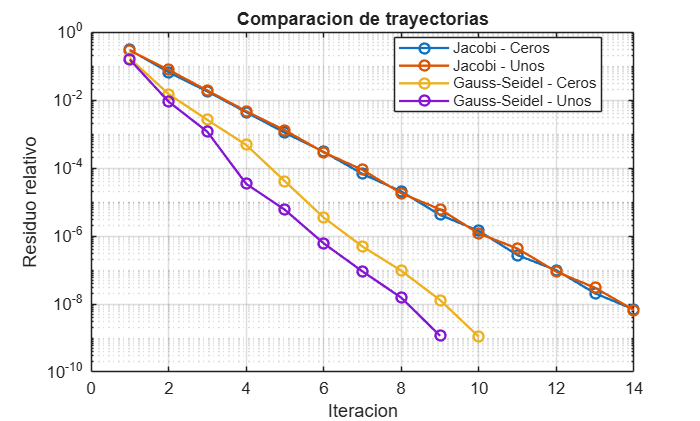

%% Comparacion de trayectorias con tol = 1e-8

figure;

indices = [2, 5, 8, 11];

for i = 1:length(indices)

    idx = indices(i);

    semilogy(1:length(historiales{idx}), ...
        max(historiales{idx},eps), ...
        '-o', 'LineWidth',1.4);

    hold on;
end

grid on;

xlabel('Iteracion');
ylabel('Residuo relativo');

legend('Jacobi - Ceros', ...
    'Jacobi - Unos', ...
    'Gauss-Seidel - Ceros', ...
    'Gauss-Seidel - Unos', ...
    'Location','best');

title('Comparacion de trayectorias');

Al evaluar los métodos de Jacobi y Gauss–Seidel con diferentes condiciones iniciales y tolerancias, se observó convergencia en los 12 experimentos. Para una tolerancia de ${10}^{-8}$, Jacobi requirió 14 iteraciones con ambas semillas, mientras que Gauss–Seidel necesitó 10 iteraciones con la semilla de ceros y 9 con la de unos. Al reducir la tolerancia de ${10}^4$ a ${10}^{-10}$, las iteraciones de Jacobi aumentaron de 7 a 18 y las de Gauss–Seidel de 5 a 12, utilizando la semilla de ceros. Los residuos finales disminuyeron, aunque los errores no lo hicieron en una proporción exactamente igual al cambio de tolerancia. Estos resultados muestran que Gauss–Seidel presentó una convergencia más rápida para el sistema estudiado y que tanto la tolerancia como la condición inicial influyen en el comportamiento numérico de los métodos.

**4.3**

**Predicción:**

Matriz original:


$$\left\lbrack \begin{array}{cccc}
6\ldotp 05 & -1 & 0 & 1\\
-1 & 6\ldotp 05 & -1 & 0\\
0 & -1 & 5\ldotp 25 & -1\\
1 & 0 & -1 & 5
\end{array}\right\rbrack \to \left\lbrack \begin{array}{cccc}
2 & 1 & 4 & 3
\end{array}\right\rbrack \to \left\lbrack \begin{array}{cccc}
-1 & 6\ldotp 05 & -1 & 0\\
6\ldotp 05 & -1 & 0 & 1\\
1 & 0 & -1 & 5\\
0 & -1 & 5\ldotp 25 & -1
\end{array}\right\rbrack$$


La matriz reordenada, resulta en una diagonal no dominante, significando que los elementos fuera de la diagonal tienen magnitudes mayores, por lo tanto se espera que Jacobi y Gauss–Seidel presenten divergencia. Esta predicción se comprobará calculando los radios espectrales de sus matrices de iteración.

    Pb = eye(4);
Pb = Pb([2 1 4 3],:);

Ab = Pb*A;
bb = Pb*b;

disp('Matriz reordenada:');

Matriz reordenada:


disp(Ab);

   -1.0000    6.0500   -1.0000         0
    6.0500   -1.0000         0    1.0000
    1.0000         0   -1.0000    5.0000
         0   -1.0000    5.2500   -1.0000




disp('Diagonal reordenada:');

Diagonal reordenada:


disp(diag(Ab));

    -1
    -1
    -1
    -1




%% Matrices de iteracion

Db = diag(diag(Ab));
Lb = tril(Ab,-1);
Ub = triu(Ab,1);

BJb = -Db\(Lb+Ub);
BGSb = -(Db+Lb)\Ub;

rhoJb = max(abs(eig(BJb)));
rhoGSb = max(abs(eig(BGSb)));

fprintf('Radio Jacobi reordenado: %.6f\n',rhoJb);

Radio Jacobi reordenado: 5.959926


fprintf('Radio GS reordenado: %.6f\n',rhoGSb);

Radio GS reordenado: 35.520714



%% Comparacion de convergencia

maxIter = 500;
tol = 1e-8;
limite = 1e10;

histJb = [];
histGSb = [];

for metodo = 1:2

    x = zeros(4,1);
    historial = zeros(maxIter,1);
    estado = "Maximo de iteraciones";

    for k = 1:maxIter

        xAnterior = x;

        if metodo == 1
            x = Db\(bb-(Lb+Ub)*xAnterior);
        else
            x = (Db+Lb)\(bb-Ub*xAnterior);
        end

        Rr = norm(bb-Ab*x,inf)/norm(bb,inf);
        historial(k) = Rr;

        if ~isfinite(Rr) || Rr > limite
            estado = "Divergencia";
            break
        end

        if Rr < tol
            estado = "Convergencia";
            break
        end
    end

    historial = historial(1:k);

    if metodo == 1
        histJb = historial;
        fprintf('\nJacobi: %s, %d iteraciones\n',estado,k);
    else
        histGSb = historial;
        fprintf('Gauss-Seidel: %s, %d iteraciones\n',estado,k);
    end
end


Jacobi: Divergencia, 14 iteraciones


Gauss-Seidel: Divergencia, 7 iteraciones


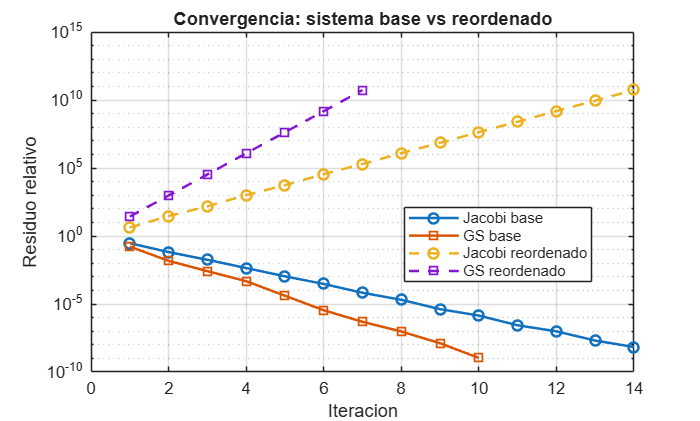


%% Grafica base vs reordenado

figure;

semilogy(1:length(resJ),resJ,'-o','LineWidth',1.5);
hold on;

semilogy(1:length(resGS),resGS,'-s','LineWidth',1.5);

semilogy(1:length(histJb),histJb,'--o','LineWidth',1.5);

semilogy(1:length(histGSb),histGSb,'--s','LineWidth',1.5);

grid on;

xlabel('Iteracion');
ylabel('Residuo relativo');

legend('Jacobi base','GS base', ...
       'Jacobi reordenado','GS reordenado', ...
       'Location','best');

title('Convergencia: sistema base vs reordenado');

El reordenamiento produjo radios espectrales aproximados de 5.960 para Jacobi y 35.521 para Gauss–Seidel, ambos mayores que uno, lo que confirma la divergencia esperada. En comparación, el sistema original presentó radios espectrales menores que uno y ambos métodos convergieron. Esto demuestra que el orden de las ecuaciones influye en la convergencia de los métodos iterativos, aunque no modifica la solución exacta del sistema.

Para recuperar un comportamiento favorable, se propone reordenar las filas como ([2,1,4,3]) sobre la matriz reordenada, recuperando así la matriz original y su dominancia diagonal estricta.

**4.4**



tol = 1e-8;
maxIter = 500;
x0 = zeros(4,1);

omegas = 0.6:0.1:1.8;

n = length(omegas);

iteracionesSOR = zeros(n,1);
residuosSOR = zeros(n,1);
tiemposSOR = zeros(n,1);
erroresSOR = zeros(n,1);
estadosSOR = strings(n,1);

historialesSOR = cell(n,1);

%% Barrido de omega

for i = 1:n

    omega = omegas(i);
    x = x0;

    historial = zeros(maxIter,1);
    convergio = false;

    tic;

    for k = 1:maxIter

        xAnterior = x;

        % Actualizacion SOR
        x = (D+omega*L)\ ...
            (omega*b + ((1-omega)*D-omega*U)*xAnterior);

        % Residuo relativo
        Rr = norm(b-A*x,inf)/norm(b,inf);

        historial(k) = Rr;

        % Proteccion numerica
        if ~all(isfinite(x)) || ~isfinite(Rr) || Rr > 1e10
            break
        end

        % Criterio de convergencia
        if Rr < tol
            convergio = true;
            break
        end

    end

    tiemposSOR(i) = toc;

    iteracionesSOR(i) = k;
    residuosSOR(i) = Rr;
    erroresSOR(i) = norm(x-xref,inf);

    historialesSOR{i} = historial(1:k);

    if convergio
        estadosSOR(i) = "Convergió";
    else
        estadosSOR(i) = "No convergió";
    end

end

%% Tabla de resultados

tablaSOR = table(omegas', iteracionesSOR, ...
    residuosSOR, tiemposSOR, erroresSOR, estadosSOR, ...
    'VariableNames', {'Omega','Iteraciones', ...
    'Residuo','Tiempo_s','Error','Estado'});

disp(tablaSOR);

    Omega    Iteraciones     Residuo      Tiempo_s       Error         Estado   
    _____    ___________    __________    _________    __________    ___________

     0.6         27         6.9132e-09    0.0034463    1.4119e-08    "Convergió"
     0.7         21         6.3832e-09    0.0001165    1.3213e-08    "Convergió"
     0.8         17         3.6873e-09     7.18e-05     6.826e-09    "Convergió"
     0.9         13         2.2984e-09     6.06e-05     3.771e-09    "Convergió"
       1         10         1.0856e-09    0.0002061     1.699e-09    "Convergió"
     1.1         11         4.4311e-09      4.9e-05    6.6315e-09    "Convergió"
     1.2         15         3.0384e-09     2.53e-05    4.5493e-09    "Convergió"
     1.3         19         4.6182e-09     3.11e-05    6.8181e-09 


%% Mejor omega por iteraciones

validos = find(estadosSOR == "Convergió");

[~,posIter] = min(iteracionesSOR(validos));
idxMejorIter = validos(posIter);

omegaMejor = omegas(idxMejorIter);

%% Mejor omega por tiempo

[~,posTiempo] = min(tiemposSOR(validos));
idxMejorTiempo = validos(posTiempo);

omegaMasRapido = omegas(idxMejorTiempo);

fprintf('\nMejor omega por iteraciones: %.2f\n',omegaMejor);


Mejor omega por iteraciones: 1.00


fprintf('Iteraciones: %d\n',iteracionesSOR(idxMejorIter));

Iteraciones: 10



fprintf('\nMejor omega por tiempo: %.2f\n',omegaMasRapido);


Mejor omega por tiempo: 1.20


fprintf('Tiempo: %.8e s\n',tiemposSOR(idxMejorTiempo));

Tiempo: 2.53000000e-05 s



%% Verificacion SOR omega = 1 y Gauss-Seidel

xSOR1 = x0;

for k = 1:maxIter

    xAnterior = xSOR1;

    xSOR1 = (D+L)\(b-U*xAnterior);

    Rr = norm(b-A*xSOR1,inf)/norm(b,inf);

    if Rr < tol
        break
    end
end

fprintf('\nDiferencia SOR(1) vs GS: %.8e\n', ...
    norm(xSOR1-xGS,inf));


Diferencia SOR(1) vs GS: 0.00000000e+00


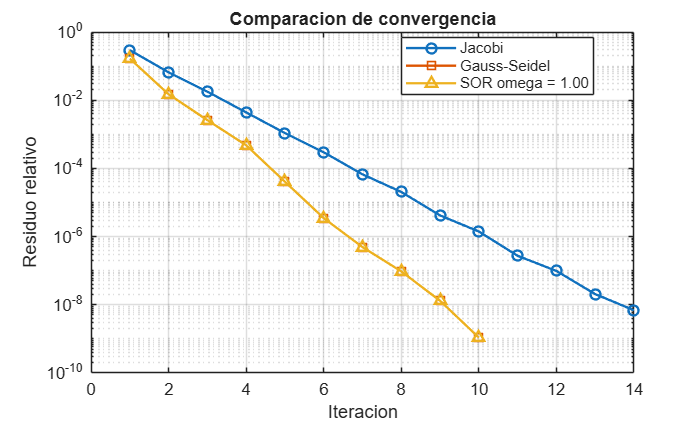


%% Grafica 1: residuos

figure;

semilogy(1:length(resJ),max(resJ,eps), ...
    '-o','LineWidth',1.4);
hold on;

semilogy(1:length(resGS),max(resGS,eps), ...
    '-s','LineWidth',1.4);

histMejor = historialesSOR{idxMejorIter};

semilogy(1:length(histMejor),max(histMejor,eps), ...
    '-^','LineWidth',1.4);

grid on;

xlabel('Iteracion');
ylabel('Residuo relativo');

legend('Jacobi','Gauss-Seidel', ...
    sprintf('SOR omega = %.2f',omegaMejor), ...
    'Location','best');

title('Comparacion de convergencia');

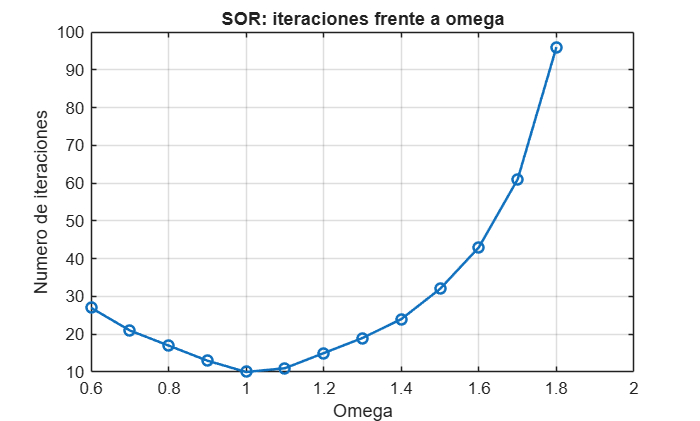


%% Grafica 2: iteraciones frente a omega

figure;

plot(omegas,iteracionesSOR,'-o','LineWidth',1.5);

grid on;

xlabel('Omega');
ylabel('Numero de iteraciones');

title('SOR: iteraciones frente a omega');

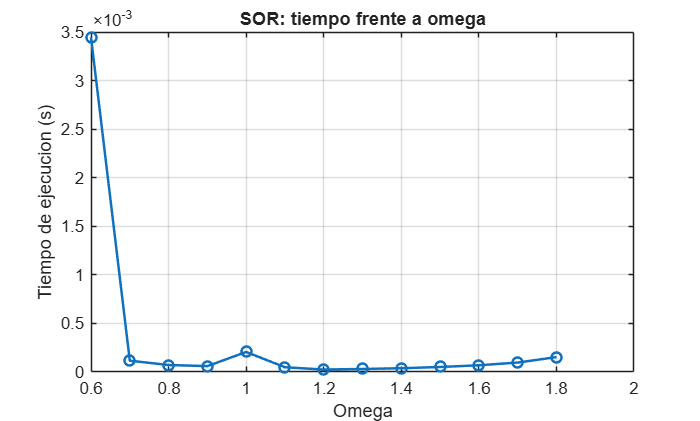


%% Grafica 3: tiempo frente a omega

figure;

plot(omegas,tiemposSOR,'-o','LineWidth',1.5);

grid on;

xlabel('Omega');
ylabel('Tiempo de ejecucion (s)');

title('SOR: tiempo frente a omega');

Al evaluar el método SOR para valores de $\omega$ entre 0.6 y 1.8, se observó convergencia en todos los casos. El menor número de iteraciones se obtuvo con $\omega =1$, requiriendo 10 iteraciones y alcanzando un residuo relativo de $1\ldotp 0856\times 10^{-9}$. Además, se verificó que este valor reproduce exactamente la solución de Gauss–Seidel, con una diferencia numérica igual a cero.

Para valores menores que uno, las iteraciones aumentaron hasta 27 con $\omega =0\ldotp 6$, mientras que para valores superiores a uno aumentaron hasta 96 con $\omega =1\ldotp 8$. El menor tiempo registrado fue de $2\ldotp 51\times {10}^{-5} s$ para  $\omega =1\ldotp 2$, con 15 iteraciones. Sin embargo, debido a la corta duración de las ejecuciones, las mediciones de tiempo pueden presentar variaciones. Por lo tanto, se concluye que para este sistema,  $\omega =1$fue la mejor elección según el número de iteraciones, aunque no presentó el menor tiempo medido.

## Punto 5.  Caso integrador de ingeniería: red lineal y elemento no lineal.

**5.1**


% Conductancias en siemens
g12 = (2 + 0.05*d7)*1e-3;
g23 = (1.5 + 0.03*d8)*1e-3;
g13 = (0.5 + 0.02*d9)*1e-3;

g10 = 1.0e-3;
g20 = 1.2e-3;

% Corriente de alimentacion en amperios
I1 = (3 + 0.1*d7)*1e-3;

% Matriz nodal
AT = [g10+g12+g13, -g12,         -g13;
    -g12,         g20+g12+g23, -g23;
    -g13,         -g23,         g13+g23];

% Vector de corrientes
iT = [I1; 0; 0];

% Solucion del sistema lineal
V = AT\iT;

V1 = V(1);
V2 = V(2);
V3 = V(3);

% Voltaje de Thevenin
Vth = V3;

fprintf('Voltaje V1 = %.8f V\n',V1);

Voltaje V1 = 1.71384300 V


fprintf('Voltaje V2 = %.8f V\n',V2);

Voltaje V2 = 1.15513084 V


fprintf('Voltaje V3 = %.8f V\n',V3);

Voltaje V3 = 1.31251454 V


fprintf('Voltaje Thevenin = %.8f V\n',Vth);

Voltaje Thevenin = 1.31251454 V



%% Balance de corrientes

% Corrientes de cada rama
I12 = g12*(V1-V2);
I23 = g23*(V2-V3);
I13 = g13*(V1-V3);

I10 = g10*V1;
I20 = g20*V2;

% Balance nodal (KCL)
balance1 = I1-I12-I13-I10;
balance2 = I12-I23-I20;
balance3 = I13+I23;

% Tabla de comprobacion
tablaBalance = table((1:3)', ...
    [balance1;balance2;balance3], ...
    abs([balance1;balance2;balance3]), ...
    'VariableNames', ...
    {'Nodo','Balance_A','ErrorAbsoluto_A'});

disp(tablaBalance);

    Nodo     Balance_A     ErrorAbsoluto_A
    ____    ___________    _______________

     1      -2.1684e-19      2.1684e-19   
     2       8.6736e-19      8.6736e-19   
     3      -5.9631e-19      5.9631e-19   



% Residuo del sistema
residuo = norm(iT-AT*V,inf);

fprintf('\nResiduo del sistema = %.8e A\n',residuo);


Residuo del sistema = 1.30104261e-18 A


Al resolver el sistema nodal se obtuvieron voltajes de 1.713843 V, 1.155131 V y 1.312515 V para los nodos 1, 2 y 3, respectivamente. Como el puerto del diodo permanece abierto, el voltaje del nodo 3 corresponde al voltaje de Thévenin de la red. El balance de corrientes presentó diferencias del orden de ${10}^{-19} \;A$, lo que confirma el cumplimiento de la ley de Kirchhoff dentro de la precisión numérica. Por lo tanto, el sistema lineal permite determinar de manera consistente el comportamiento de la red resistiva.

**5.2**

% Desactivar fuente independiente
Iprueba = 1e-3;
% Aplicar corriente de prueba en nodo 3
iPrueba = [0; 0; Iprueba];

% Resolver sistema lineal
Vprueba = AT\iPrueba;

V3prueba = Vprueba(3);

% Resistencia de Thevenin
Rth = V3prueba/Iprueba;

fprintf('Voltaje de prueba V1 = %.8f V\n',Vprueba(1));

Voltaje de prueba V1 = 0.42339179 V


fprintf('Voltaje de prueba V2 = %.8f V\n',Vprueba(2));

Voltaje de prueba V2 = 0.48050684 V


fprintf('Voltaje de prueba V3 = %.8f V\n',V3prueba);

Voltaje de prueba V3 = 0.93390166 V



fprintf('\nResistencia de Thevenin = %.8f Ohm\n',Rth);


Resistencia de Thevenin = 933.90166339 Ohm



% Comprobacion
residuoPrueba = norm(iPrueba-AT*Vprueba,inf);

fprintf('Residuo del sistema = %.8e A\n',residuoPrueba);

Residuo del sistema = 0.00000000e+00 A


Al desactivar la fuente independiente y aplicar una corriente de prueba de 1 mA en el nodo 3, se obtuvo un voltaje de 0.93390166 V, correspondiente a una resistencia de Thévenin de 933.90166 Ω. El residuo del sistema fue cero a la precisión mostrada, lo que confirma la consistencia numérica de la solución. Tanto el cálculo del voltaje de Thévenin como el de la resistencia equivalente se realizaron mediante sistemas lineales, ya que las conductancias permanecieron constantes y únicamente cambió el vector de corrientes.

**5.3**

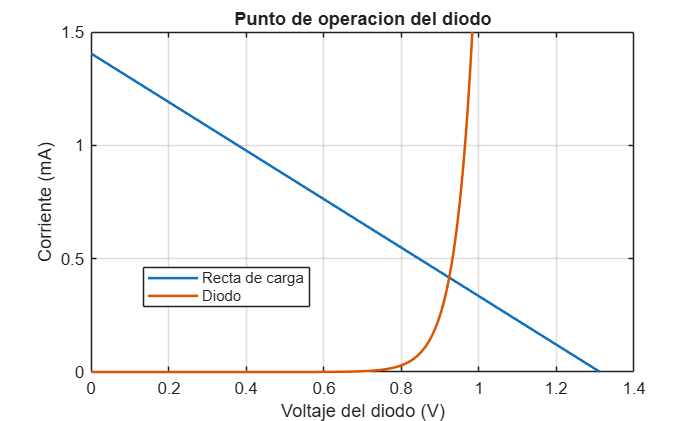

Is = 1e-12;
n = 1.8;
VT = 0.02585;

F = @(VD) Vth - VD - Rth*Is*expm1(VD/(n*VT));

dF = @(VD) -1 - (Rth*Is/(n*VT))*exp(VD/(n*VT));

tol = 1e-10;
maxIter = 100;

%% Grafica: recta de carga y diodo

VDgraf = linspace(0,Vth,1000);

Icarga = (Vth-VDgraf)/Rth;
Idiodo = Is*expm1(VDgraf/(n*VT));

figure;
plot(VDgraf,Icarga*1e3,'LineWidth',1.5);
hold on;
plot(VDgraf,Idiodo*1e3,'LineWidth',1.5);
grid on;

xlabel('Voltaje del diodo (V)');
ylabel('Corriente (mA)');
legend('Recta de carga','Diodo','Location','best');
title('Punto de operacion del diodo');
ylim([0 1.5]);


%% Biseccion

a = 0;
b = Vth;

if F(a)*F(b) >= 0
    error('El intervalo no presenta cambio de signo');
end

for kB = 1:maxIter

    VD_B = (a+b)/2;

    if abs(F(VD_B)) < tol || (b-a)/2 < tol
        break
    end

    if F(a)*F(VD_B) < 0
        b = VD_B;
    else
        a = VD_B;
    end
end

resB = abs(F(VD_B));

%% Newton-Raphson

VD_N = 0.9;

for kN = 1:maxIter

    VDnuevo = VD_N - F(VD_N)/dF(VD_N);

    if ~isfinite(VDnuevo)
        error('Newton produjo un valor no finito');
    end

    VD_N = VDnuevo;

    if abs(F(VD_N)) < tol
        break
    end
end

resN = abs(F(VD_N));

%% Comparacion

tabla53 = table( ...
    ["Biseccion";"Newton-Raphson"], ...
    [VD_B;VD_N], ...
    [resB;resN], ...
    [kB;kN], ...
    'VariableNames', ...
    {'Metodo','Voltaje_V','Residuo_V','Iteraciones'});

disp(tabla53);

         Metodo         Voltaje_V    Residuo_V     Iteraciones
    ________________    _________    __________    ___________

    "Biseccion"          0.9235      8.1427e-11        34     
    "Newton-Raphson"     0.9235      9.2203e-11         4     



%% Sensibilidad a la semilla de Newton

semillasN = [0.5 0.7 0.9 1.1 1.3];

iterN = zeros(length(semillasN),1);
raizN = zeros(length(semillasN),1);
resNuevos = zeros(length(semillasN),1);
estadoN = strings(length(semillasN),1);

for j = 1:length(semillasN)

    x = semillasN(j);
    convergio = false;

    for k = 1:maxIter

        % Evaluacion segura
        if ~isfinite(F(x)) || ~isfinite(dF(x)) || ...
                abs(dF(x)) < 1e-14
            break
        end

        xNuevo = x - F(x)/dF(x);

        if ~isfinite(xNuevo)
            break
        end

        x = xNuevo;

        if abs(F(x)) < tol
            convergio = true;
            break
        end
    end

    iterN(j) = k;
    raizN(j) = x;
    resNuevos(j) = abs(F(x));

    if convergio
        estadoN(j) = "Convergió";
    else
        estadoN(j) = "No convergió";
    end
end

tablaSensibilidad = table(semillasN',raizN, ...
    resNuevos,iterN,estadoN, ...
    'VariableNames', ...
    {'Semilla','Raiz','Residuo','Iteraciones','Estado'});

disp(tablaSensibilidad);

    Semilla     Raiz      Residuo      Iteraciones      Estado   
    _______    ______    __________    ___________    ___________

      0.5      0.9235    7.2164e-16        14         "Convergió"
      0.7      0.9235    7.2164e-16        13         "Convergió"
      0.9      0.9235    9.2203e-11         4         "Convergió"
      1.1      0.9235     5.651e-14         8         "Convergió"
      1.3      0.9235    1.8682e-11        12         "Convergió"



**5.4**

VD = VD_N;

% Corriente Thevenin
ID = (Vth-VD)/Rth;

% Corriente Shockley
ID_Shockley = Is*expm1(VD/(n*VT));

% Potencia del diodo
PD = VD*ID;

% Diferencia entre corrientes
diferenciaI = abs(ID-ID_Shockley);

errorRelI = diferenciaI/max(abs(ID_Shockley),eps)*100;

fprintf('Voltaje del diodo = %.8f V\n',VD);

Voltaje del diodo = 0.92350420 V


fprintf('Corriente Thevenin = %.8e A\n',ID);

Corriente Thevenin = 4.16543149e-04 A


fprintf('Corriente Shockley = %.8e A\n',ID_Shockley);

Corriente Shockley = 4.16543149e-04 A


fprintf('Potencia del diodo = %.8e W\n',PD);

Potencia del diodo = 3.84679349e-04 W



fprintf('\nDiferencia entre corrientes = %.8e A\n',diferenciaI);


Diferencia entre corrientes = 9.87285340e-14 A


fprintf('Error relativo entre corrientes = %.8e %%\n',errorRelI);

Error relativo entre corrientes = 2.37018744e-08 %


%g12=+5%

g12_n = 1.05*g12;

% Nueva matriz nodal
AT_n = [g10+g12_n+g13, -g12_n,         -g13;
            -g12_n,         g20+g12_n+g23, -g23;
            -g13,               -g23,              g13+g23];

%% Nuevo voltaje de Thevenin

V_n = AT_n\iT;

Vth_n = V_n(3);

%% Nueva resistencia de Thevenin

Vprueba_n = AT_n\iPrueba;

Rth_n = Vprueba_n(3)/Iprueba;

%% Nuevo punto de operacion del diodo

F_nueva = @(VD) Vth_n - VD - ...
    Rth_n*Is*expm1(VD/(n*VT));

% Metodo cerrado: biseccion
a = 0;
b = Vth_n;

tol = 1e-10;
maxIter = 100;

if F_nueva(a)*F_nueva(b) >= 0
    error('Intervalo invalido para biseccion');
end

for k = 1:maxIter

    VD_n = (a+b)/2;

    if abs(F_nueva(VD_n)) < tol || ...
            (b-a)/2 < tol
        break
    end

    if F_nueva(a)*F_nueva(VD_n) < 0
        b = VD_n;
    else
        a = VD_n;
    end
end

%% Nueva corriente y potencia

ID_n = (Vth_n-VD_n)/Rth_n;

ID_Shockley_n = Is*expm1(VD_n/(n*VT));

PD_n = VD_n*ID_n;

%% Cambios relativos porcentuales

cambioVth = (Vth_n-Vth)/abs(Vth)*100;
cambioRth = (Rth_n-Rth)/abs(Rth)*100;
cambioVD = (VD_n-VD)/abs(VD)*100;
cambioID = (ID_n-ID)/abs(ID)*100;

%% Tabla comparativa

Parametro = ["Vth (V)";
             "Rth (Ohm)";
             "VD (V)";
             "ID (mA)"];

Original = [Vth;
            Rth;
            VD;
            ID*1e3];

Perturbado = [Vth_n;
              Rth_n;
              VD_n;
              ID_n*1e3];

CambioRelativo_pct = [cambioVth;
                      cambioRth;
                      cambioVD;
                      cambioID];

tabla54 = table(Parametro,Original,Perturbado, ...
    CambioRelativo_pct);

disp(tabla54);

     Parametro     Original    Perturbado    CambioRelativo_pct
    ___________    ________    __________    __________________

    "Vth (V)"       1.3125       1.3157            0.24104     
    "Rth (Ohm)"      933.9       933.58           -0.03463     
    "VD (V)"        0.9235      0.92386            0.03804     
    "ID (mA)"      0.41654       0.4197            0.75786     



%% Comprobacion del nuevo punto de operacion

fprintf('\nResiduo nuevo = %.8e V\n',abs(F_nueva(VD_n)));


Residuo nuevo = 5.11758524e-10 V


fprintf('Diferencia entre corrientes = %.8e A\n', ...
    abs(ID_n-ID_Shockley_n));

Diferencia entre corrientes = 5.48168824e-13 A


fprintf('Potencia nueva = %.8e W\n',PD_n);

Potencia nueva = 3.87742118e-04 W


Los métodos de bisección y Newton–Raphson convergieron al mismo punto de operación del diodo, con un voltaje aproximado de 0.9235 V. Sin embargo, bisección requirió 34 iteraciones, mientras que Newton–Raphson necesitó únicamente 4, evidenciando una convergencia más rápida de este último para la semilla seleccionada. Al evaluar la sensibilidad de Newton–Raphson con cinco semillas entre 0.5 V y 1.3 V, todas convergieron a la misma raíz, aunque el número de iteraciones varió entre 4 y 14. Esto demuestra que la elección de la semilla influye en la rapidez de convergencia, mientras que bisección ofrece mayor garantía de convergencia cuando se dispone de un intervalo válido con cambio de signo.

La corriente del diodo calculada mediante el equivalente de Thévenin fue aproximadamente 0.41654 mA, consistente con la obtenida mediante la ecuación de Shockley. A partir del voltaje y la corriente se obtiene una potencia disipada cercana a $0\ldotp 385\times {10}^{-3} \;W$, lo que confirma un comportamiento físicamente consistente del punto de operación.

Finalmente, la perturbación modificó ligeramente los parámetros del equivalente lineal de Thévenin, pero su efecto sobre el punto de operación no fue uniforme. Aunque el voltaje del diodo presentó una variación pequeña, la corriente mostró una mayor sensibilidad dada la relación exponencial de Shockley. Esto evidencia que la etapa no lineal puede amplificar pequeñas variaciones de las condiciones eléctricas de alimentación.

**Análisis requerido:**

El cálculo del equivalente de Thévenin corresponde a un problema lineal, ya que la red está formada por conductancias constantes y sus ecuaciones nodales pueden expresarse mediante el sistema (A_TV=i). Por esta razón, tanto el voltaje como la resistencia de Thévenin se obtienen resolviendo sistemas de ecuaciones lineales. En cambio, al conectar el diodo aparece la relación exponencial entre corriente y voltaje descrita por la ecuación de Shockley, lo que obliga a resolver una ecuación no lineal mediante métodos numéricos como bisección o Newton–Raphson.

Al incrementar la conductancia $g_{12}$ un 5 %, el voltaje de Thévenin aumentó un 0.24104 %, mientras que la resistencia de Thévenin disminuyó un 0.03463 %. Como consecuencia, el voltaje del diodo aumentó un 0.03804 % y su corriente un 0.75786 %. La corriente presentó la mayor variación relativa, mientras que el voltaje del diodo fue el menos afectado. Esto se explica por la característica exponencial del diodo, donde pequeñas variaciones de voltaje pueden producir cambios mayores en la corriente.

Estos resultados indican que la corriente del diodo fue la variable más sensible a la perturbación. Aunque el voltaje del diodo cambió muy poco, la dependencia exponencial de la corriente respecto al voltaje produjo una variación relativa considerablemente mayor. Por tanto, para este circuito y esta perturbación, el mayor efecto relativo se observó en la corriente de la etapa no lineal, mientras que los parámetros del equivalente de Thévenin presentaron cambios menores. Esto demuestra que una perturbación pequeña en la red lineal puede producir una respuesta proporcionalmente mayor en una variable de la etapa no lineal.